# Medida equivalente de martingala y valoración de opciones

**Autor:** Luis Martínez Gonzales. **Asesor:** Freddy H. Marín. Procesos Estocásticos II (CM0438), Universidad EAFIT.

Se modela la tasa de cambio dólares por euro (EUR/USD, serie DEXUSEU de FRED) como un movimiento browniano geométrico, $dS_t = \mu S_t\,dt + \sigma S_t\,dB_t$, se estiman sus parámetros, se evalúan los pronósticos sobre la muestra y se valoran opciones call europeas con Black-Scholes, árbol binomial, Monte Carlo y diferencias finitas explícitas.

## 1. Configuración

clearvars
warning('off', 'backtrace')
% Datos (FRED, consultados el 11 de noviembre de 2026)
cfg.archivo       = 'DEXUSEU.xlsx';
cfg.hoja          = 'Daily';
cfg.colFecha      = 'observation_date';
cfg.colPrecio     = 'DEXUSEU';
cfg.activo        = 'USD por EUR';
cfg.fuente        = 'FRED, Federal Reserve Bank of St. Louis (H.10, Board of Governors)';
cfg.url           = 'https://fred.stlouisfed.org/series/DEXUSEU';
cfg.fechaConsulta = datetime(2026,11,11);
cfg.n             = 251;        % precios de la ventana (rúbrica: al menos 250)
cfg.dt            = 1/252;      % un día hábil, en años
% Pruebas
cfg.alpha   = 0.05;             % nivel de significancia
cfg.rezagos = 5;                % rezagos de ARCH y Ljung-Box (como el script del curso)
% Estimación y pronósticos
cfg.k          = 10000;         % trayectorias (rúbrica)
cfg.esquema    = 'euler';       % 'euler' (como el curso) o 'exacta'
cfg.semilla    = 2026;
cfg.nivelBanda = 0.95;
cfg.nGraficar  = 200;           % trayectorias dibujadas en las figuras
% Valoración
cfg.r           = 0.05;                   % tasa libre de riesgo (rúbrica)
cfg.Tvec        = [1, 1/2, 1/3, 1/4];     % vencimientos en años (rúbrica)
cfg.derivaK     = 'mu';                   % deriva de las trayectorias que dan los K: 'mu' o 'r'
cfg.percentiles = [10 30 50 70 90];       % percentiles de S_T que se usan como K
cfg.decimalesK  = 4;                      % la serie cotiza con 4 decimales
cfg.nBin        = 1000;                   % binomial: pasos del árbol (PDF del curso)
cfg.tipoP       = 'curso';                % binomial: p del PDF ('curso') o exacta ('crr')
cfg.nConv       = [25 50 100 200 400 800 1000 2000];
cfg.W           = 1000;                   % Monte Carlo: repeticiones (PDF)
cfg.kMC         = 10000;                  % Monte Carlo: trayectorias por repetición (PDF)
cfg.mMC         = 200;                    % Monte Carlo: pasos de Euler del código del curso
cfg.WCurso      = 10;                     % Monte Carlo: repeticiones del código del curso en la validación
cfg.nS0         = 800;                    % dif. finitas: ds = S0/nS0
cfg.SmaxFactorK = 2;                      % dif. finitas: Smax = 2K (código del PDF)
cfg.nS0Conv     = [100 200 400 800 1600];
cfg.dsEj        = [10 5 2 1 0.5];
cfg.dsInestable = 2;
cfg.factoresEst = [1 1.05 1.2 1.5];
dt = cfg.dt;

# Parte A. Datos y condiciones del MBG

## A.1 Carga y control de calidad

Últimos 251 precios hasta la fecha de consulta. Los días sin dato (festivos) se eliminan.

opts   = detectImportOptions(cfg.archivo, 'Sheet', cfg.hoja, 'VariableNamingRule', 'preserve');
Tdatos = readtable(cfg.archivo, opts);
fechas = Tdatos.(cfg.colFecha);
if ~isdatetime(fechas), fechas = datetime(string(fechas)); end
precio = Tdatos.(cfg.colPrecio);
if ~isnumeric(precio), precio = str2double(erase(string(precio), ',')); end
precio = precio(:);
[fechas, ord] = sort(fechas, 'ascend');
precio     = precio(ord);
nFechasDup = numel(fechas) - numel(unique(fechas));
nNaN       = sum(isnan(precio));
FechasEliminadas = table(fechas(isnan(precio)), day(fechas(isnan(precio)), 'name'), ...
                         'VariableNames', {'Fecha', 'Dia'})

FechasEliminadas = 11×2 table
       Fecha           Dia     
    ___________    ____________

    11-Nov-2025    {'Tuesday' }
    27-Nov-2025    {'Thursday'}
    25-Dec-2025    {'Thursday'}
    01-Jan-2026    {'Thursday'}
    19-Jan-2026    {'Monday'  }
    16-Feb-2026    {'Monday'  }
    25-May-2026    {'Monday'  }
    19-Jun-2026    {'Friday'  }
    03-Jul-2026    {'Friday'  }
    07-Sep-2026    {'Monday'  }
    12-Oct-2026    {'Monday'  }


validos = ~isnan(precio) & ~isnat(fechas);
precio  = precio(validos);
fechas  = fechas(validos);
nNoPos  = sum(precio <= 0);
X = precio(end-cfg.n+1:end);           % columna: X(1) el más antiguo, X(N) el último dato
F = fechas(end-cfg.n+1:end);
N = numel(X);
Calidad = table(["Activo"; "Fuente"; "Fecha inicial"; "Fecha final"; "Precios en la ventana"; ...
                 "Días sin dato eliminados"; "Fechas duplicadas"; "Datos en fin de semana"; ...
                 "Precios <= 0"; "% de retornos iguales a cero"; "Días entre el último dato y la consulta"], ...
                [string(cfg.activo); string(cfg.fuente); string(F(1)); string(F(end)); string(N); ...
                 string(nNaN); string(nFechasDup); string(sum(isweekend(F))); string(nNoPos); ...
                 string(round(100*mean(diff(X) == 0), 2)); string(days(cfg.fechaConsulta - F(end)))], ...
                'VariableNames', {'Control', 'Valor'})

Calidad = 11×2 table
                     Control                                                    Valor                                
    _________________________________________    ____________________________________________________________________

    "Activo"                                     "USD por EUR"                                                       
    "Fuente"                                     "FRED, Federal Reserve Bank of St. Louis (H.10, Board of Governors)"
    "Fecha inicial"                              "06-Nov-2025"                                                       
    "Fecha final"                                "06-Nov-2026"                                                       
    "Precios en la ventana"                      "251"                                                               
    "Días sin dato eliminados"                   "11"                               

## A.2 Descripción estadística

Retornos simples $R_t = (S_{t+1} - S_t)/S_t$ y log-retornos $r_t = \ln(S_{t+1}/S_t)$. La curtosis de MATLAB vale 3 para una normal.

R  = diff(X) ./ X(1:end-1);        % retornos simples
rl = diff(log(X));                 % log-retornos
estad  = @(x) [min(x) max(x) mean(x) median(x) var(x) std(x) kurtosis(x) skewness(x)];
Descriptivas = array2table([estad(X); estad(R); estad(rl)], ...
    'VariableNames', {'Min', 'Max', 'Media', 'Mediana', 'Varianza', 'DesvEst', 'Curtosis', 'Asimetria'}, ...
    'RowNames', {'Precio', 'Retorno simple', 'Log-retorno'})

Descriptivas = 3×8 table
                         Min         Max          Media         Mediana       Varianza      DesvEst     Curtosis    Asimetria
                      _________    ________    ___________    ___________    __________    _________    ________    _________

    Precio               1.1123       1.198         1.1575         1.1598    0.00033369     0.018267     2.8815     -0.54131 
    Retorno simple    -0.011166    0.012122    -0.00012978    -0.00021951    1.1947e-05    0.0034564     4.7275      0.28099 
    Log-retorno       -0.011228    0.012049    -0.00013574    -0.00021954    1.1939e-05    0.0034553     4.7133      0.26213 


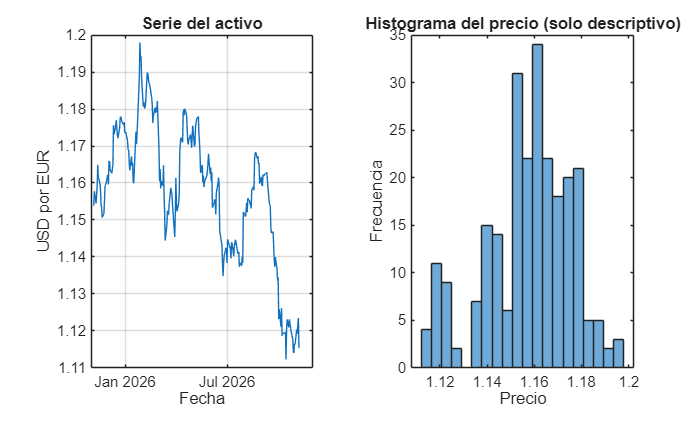

figure
tiledlayout(1, 2)
nexttile
plot(F, X); grid on
xlabel('Fecha'); ylabel('USD por EUR'); title('Serie del activo')
nexttile
histogram(X, 20)
xlabel('Precio'); ylabel('Frecuencia'); title('Histograma del precio (solo descriptivo)')

## A.3 Autocorrelación parcial, dimensión fractal y exponente de Hurst

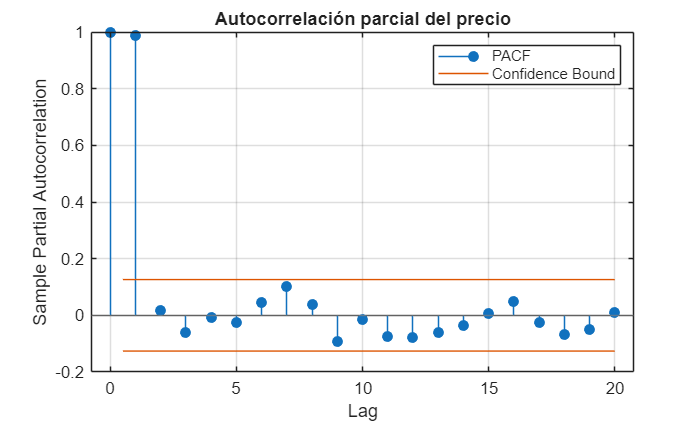

figure
parcorr(X)
title('Autocorrelación parcial del precio')

DFr = fractalvol(X);
[EH, sEH] = genhurst(X);
Fractal = table(DFr, EH, sEH, DFr + EH, abs(EH - 0.5)/sEH, ...
    'VariableNames', {'DimensionFractal', 'Hurst', 'DesvEst_Hurst', 'Suma', 'DistanciaA05_en_desv'})

Fractal = 1×5 table
    DimensionFractal     Hurst     DesvEst_Hurst    Suma     DistanciaA05_en_desv
    ________________    _______    _____________    _____    ____________________

         1.3048         0.51022       0.02517       1.815          0.40605       


## A.4 Retornos, colas y saltos

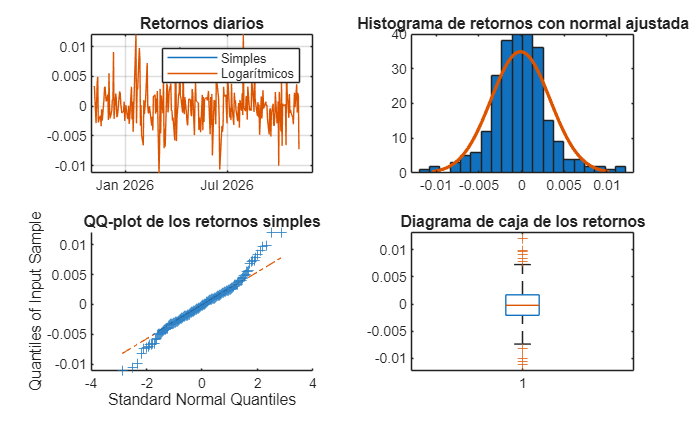

figure
tiledlayout(2, 2)
nexttile
plot(F(2:end), R, F(2:end), rl); grid on
legend('Simples', 'Logarítmicos'); title('Retornos diarios')
nexttile
histfit(R, 20); title('Histograma de retornos con normal ajustada')
nexttile
qqplot(R); title('QQ-plot de los retornos simples')
nexttile
boxplot(R); title('Diagrama de caja de los retornos')

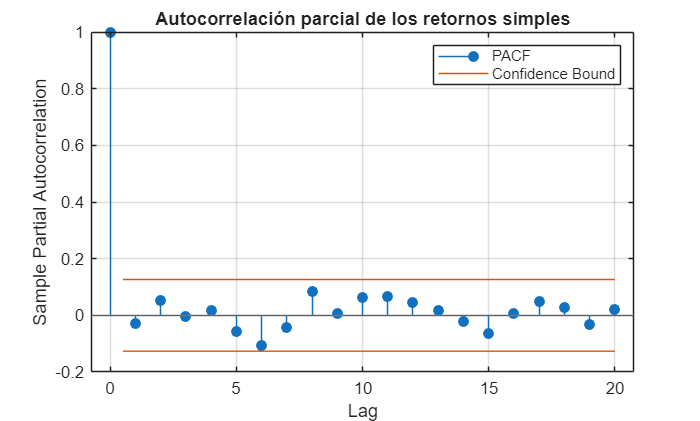

figure
parcorr(R)
title('Autocorrelación parcial de los retornos simples')

[~, ix] = maxk(abs(rl), 5);
MayoresMovimientos = table(F(ix+1), rl(ix), X(ix), X(ix+1), ...
    'VariableNames', {'Fecha', 'LogRetorno', 'PrecioAnterior', 'Precio'})

MayoresMovimientos = 5×4 table
       Fecha       LogRetorno    PrecioAnterior    Precio
    ___________    __________    ______________    ______

    30-Jul-2026     0.012049         1.1384        1.1522
    20-Jan-2026     0.011998         1.1599        1.1739
    02-Mar-2026    -0.011228         1.1822         1.169
    18-Jun-2026    -0.010667         1.1593         1.147
    01-Oct-2026     -0.01001         1.1345        1.1232


desvR   = R - mean(R);
zMax    = max(abs(desvR))/std(R);
aporte2 = 100*sum(maxk(desvR.^2, 2))/sum(desvR.^2);
hayAlertaSalto = zMax > 6 || aporte2 > 25;
fprintf('Mayor movimiento: %.1f desviaciones estándar | dos días más extremos: %.1f %% de la varianza | alerta de salto: %s\n', ...
        zMax, aporte2, siNo(hayAlertaSalto));

Mayor movimiento: 3.5 desviaciones estándar | dos días más extremos: 10.0 % de la varianza | alerta de salto: no


## A.5 Batería de pruebas

`Cumple` indica si el resultado es el que exige el MBG (en la ADF se desea rechazar $H_0$).

PruebasSimples = bateriaPruebas(R,  dt, cfg.alpha, cfg.rezagos);

PruebasLog     = bateriaPruebas(rl, dt, cfg.alpha, cfg.rezagos);

verCols = {'Prueba', 'Condicion', 'H0', 'Estadistico', 'ValorP', 'h', 'Cumple'};
PruebasRetornosSimples = PruebasSimples(:, verCols)

PruebasRetornosSimples = 8×7 table
               Prueba                    Condicion                   H0              Estadistico     ValorP      h    Cumple
    ____________________________    ____________________    _____________________    ___________    _________    _    ______

    "Jarque-Bera"                   "Normalidad"            "Normal"                    34.375          0.001    1    false 
    "Kolmogorov-Smirnov sobre Z"    "Normalidad"            "Z ~ N(0,1)"              0.069613        0.16909    0    true  
    "Anderson-Darling"              "Normalidad"            "Normal"                    1.7829         0.0005    1    false 
    "Lilliefors"                    "Normalidad"            "Normal"                  0.069613      0

PruebasLogRetornos     = PruebasLog(:, verCols)

PruebasLogRetornos = 8×7 table
               Prueba                    Condicion                   H0              Estadistico     ValorP      h    Cumple
    ____________________________    ____________________    _____________________    ___________    _________    _    ______

    "Jarque-Bera"                   "Normalidad"            "Normal"                    33.441          0.001    1    false 
    "Kolmogorov-Smirnov sobre Z"    "Normalidad"            "Z ~ N(0,1)"              0.069286        0.17301    0    true  
    "Anderson-Darling"              "Normalidad"            "Normal"                    1.7661         0.0005    1    false 
    "Lilliefors"                    "Normalidad"            "Normal"                  0.069286      0.005

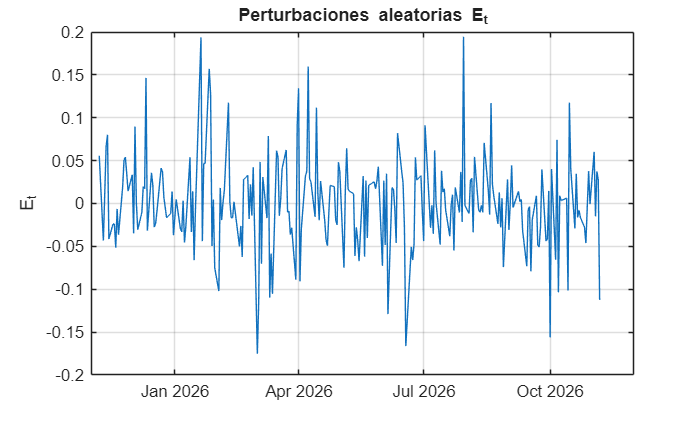

Et = (R - mean(R))/sqrt(dt);
figure
plot(F(2:end), Et); grid on
ylabel('E_t'); title('Perturbaciones aleatorias E_t')

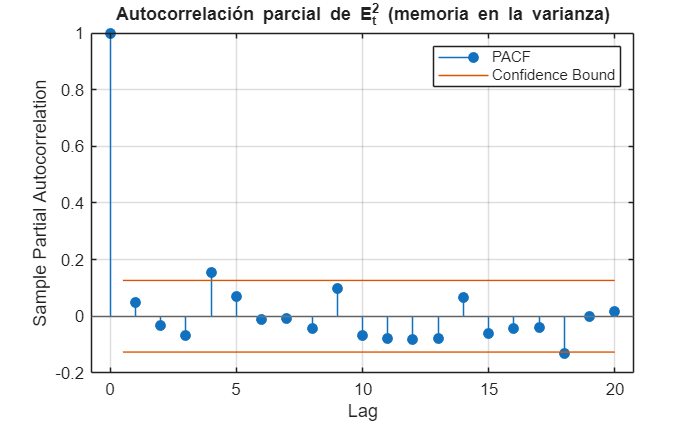

figure
parcorr(Et.^2)
title('Autocorrelación parcial de E_t^2 (memoria en la varianza)')

## A.6 Volatilidad acumulada

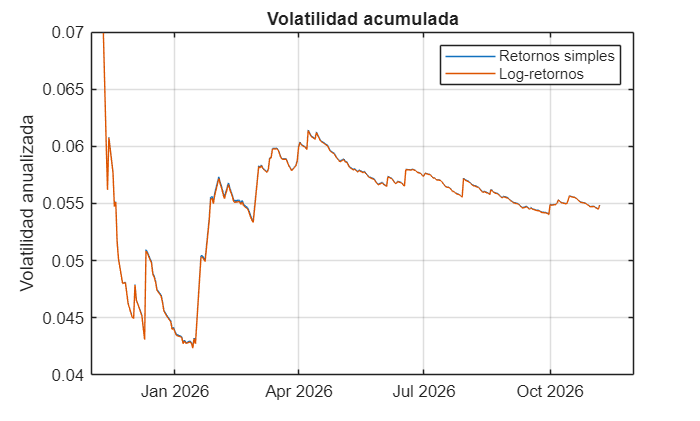

VE = nan(N-1, 1);  VEl = nan(N-1, 1);
for j = 2:N-1
    VE(j)  = std(R(1:j))/sqrt(dt);
    VEl(j) = std(rl(1:j))/sqrt(dt);
end
figure
plot(F(2:end), VE, F(2:end), VEl); grid on
legend('Retornos simples', 'Log-retornos'); ylabel('Volatilidad anualizada')
title('Volatilidad acumulada')

fprintf('Volatilidad final: %.4f (retornos simples) | %.4f (log-retornos)\n', VE(end), VEl(end));

Volatilidad final: 0.0549 (retornos simples) | 0.0549 (log-retornos)


## A.7 Lectura por condición

Se cumplen estacionariedad, independencia y varianza constante, sin saltos y con Hurst compatible con 0.5. La normalidad la rechazan Jarque-Bera, Anderson-Darling y Lilliefors por colas pesadas; KS sobre $Z$ no la rechaza.

CondicionesRetornosSimples = tablaCondiciones(PruebasSimples, hayAlertaSalto, zMax, aporte2, EH, sEH)

CondicionesRetornosSimples = 6×3 table
             Condicion              Cumple                                Evidencia                            
    ____________________________    ______    _________________________________________________________________

    "Estacionariedad"               true      "ADF: p = 0.0010 (aquí se desea rechazar)"                       
    "Independencia"                 true      "Ljung-Box sobre retornos: p = 0.8689"                           
    "Varianza constante"            true      "ARCH: p = 0.1136; Ljung-Box sobre Et^2: p = 0.0910"             
    "Normalidad"                    false     "Rechazan 3 de 3 pruebas fiables; KS sobre Z: p = 0.1691"        
    "Sin saltos"                    true      "Mayor movimiento 3.5 desv. est.; 2 días = 10.0 % de la varianza"
    "Carácter browniano (Hurst)"    true      "H = 0.510, a 0.4 desv. est.

CondicionesLogRetornos     = tablaCondiciones(PruebasLog, hayAlertaSalto, zMax, aporte2, EH, sEH)

CondicionesLogRetornos = 6×3 table
             Condicion              Cumple                                Evidencia                            
    ____________________________    ______    _________________________________________________________________

    "Estacionariedad"               true      "ADF: p = 0.0010 (aquí se desea rechazar)"                       
    "Independencia"                 true      "Ljung-Box sobre retornos: p = 0.8656"                           
    "Varianza constante"            true      "ARCH: p = 0.1182; Ljung-Box sobre Et^2: p = 0.0955"             
    "Normalidad"                    false     "Rechazan 3 de 3 pruebas fiables; KS sobre Z: p = 0.1730"        
    "Sin saltos"                    true      "Mayor movimiento 3.5 desv. est.; 2 días = 10.0 % de la varianza"
    "Carácter browniano (Hurst)"    true      "H = 0.510, a 0.4 desv. est. de 

# Parte B. Estimación y pronósticos

## B.1 Estimación de los parámetros

$\hat\mu = \bar R/\Delta t$, $\hat\sigma = s_R/\sqrt{\Delta t}$, $SE(\hat\mu) = \hat\sigma/\sqrt{n\Delta t}$, $SE(\hat\sigma) = \hat\sigma/\sqrt{2n}$.

X = X(:)';                          % de aquí en adelante X es un vector fila
R  = diff(X) ./ X(1:end-1);
rl = diff(log(X));
nRet  = N - 1;
anios = nRet*dt;
muS  = mean(R)/dt;            sigS = sqrt(var(R)/dt);          % retornos simples (curso)
sigL = std(rl)/sqrt(dt);      muL  = mean(rl)/dt + sigL^2/2;    % log-retornos
muest = muS;  sigmaest = sigS;                                  % pareja coherente con Euler
seSig = sigmaest/sqrt(2*nRet);
seMu  = sigmaest/sqrt(anios);
Parametros = table(["Retornos simples (usados)"; "Log-retornos"], [muS; muL], [sigS; sigL], ...
                   [seMu; NaN], [seSig; NaN], ...
                   ["[" + sprintf('%+.4f, %+.4f', muest + [-1 1]*1.96*seMu) + "]"; ""], ...
                   ["[" + sprintf('%.4f, %.4f', sigmaest + [-1 1]*1.96*seSig) + "]"; ""], ...
                   'VariableNames', {'Estimacion', 'mu', 'sigma', 'SE_mu', 'SE_sigma', 'IC95_mu', 'IC95_sigma'})

Parametros = 2×7 table
            Estimacion                mu         sigma       SE_mu      SE_sigma           IC95_mu               IC95_sigma    
    ___________________________    _________    ________    ________    _________    ____________________    __________________

    "Retornos simples (usados)"    -0.032705    0.054869    0.055088    0.0024538    "[-0.1407, +0.0753]"    "[0.0501, 0.0597]"
    "Log-retornos"                 -0.032702    0.054851         NaN          NaN    ""                      ""                


## B.2 Pronóstico inducido

$X_j^{(i)} = X_{j-1}\left(1 + \hat\mu\,\Delta t + \hat\sigma\sqrt{\Delta t}\,Z_j^{(i)}\right)$, con $X_{j-1}$ el dato real y 10.000 trayectorias.

rng(cfg.semilla);
k  = cfg.k;
Zi = randn(k, N-1);
XI = zeros(k, N);
XI(:,1)   = X(1);
XI(:,2:N) = X(1:end-1) .* pasoMBG(muest, sigmaest, dt, Zi, cfg.esquema);
XIbucle = zeros(3, N);                  % tres trayectorias con los bucles del curso
for i = 1:3
    XIbucle(i,1) = X(1);
    for j = 2:N
        XIbucle(i,j) = X(j-1) + muest*X(j-1)*dt + sigmaest*X(j-1)*sqrt(dt)*Zi(i,j-1);
    end
end
fprintf('Bucles del curso frente a versión vectorizada: diferencia máxima = %.2e\n', ...
        max(abs(XIbucle - XI(1:3,:)), [], 'all'));

Bucles del curso frente a versión vectorizada: diferencia máxima = 4.44e-16


[MetI, VECXI, CXICI] = metricas(X, XI, cfg.nivelBanda);
MetricasInducido = tablaMetricas("Inducido", MetI, cfg.nivelBanda, nRet)

MetricasInducido = 1×11 table
    Pronostico    MAPE_min    MAPE_medio    MAPE_max    MAPE_tray_media    MAE_tray_media    RMSE_tray_media    Cobertura_pct    Dias_fuera    Dias_fuera_esperados    R2_tray_media
    __________    ________    __________    ________    _______________    ______________    _______________    _____________    __________    ____________________    _____________

    "Inducido"    0.32009      0.38228      0.45086         0.25574          0.0029595          0.0039934           92.8             18                12.5               0.95238   


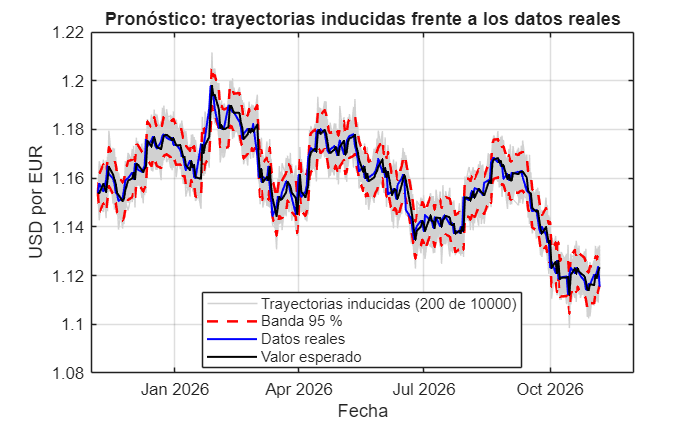

figuraPronostico(X, XI, VECXI, CXICI, F, cfg, 'inducidas');

## B.3 Pronóstico simulado

$X_j^{(i)} = X_{j-1}^{(i)}\left(1 + \hat\mu\,\Delta t + \hat\sigma\sqrt{\Delta t}\,Z_j^{(i)}\right)$, partiendo de $X_1$ con 10.000 trayectorias.

Zs = randn(k, N-1);
XS = zeros(k, N);
XS(:,1) = X(1);
for j = 2:N
    XS(:,j) = XS(:,j-1) .* pasoMBG(muest, sigmaest, dt, Zs(:,j-1), cfg.esquema);
end
[MetS, VECXS, CXSCI] = metricas(X, XS, cfg.nivelBanda);
MetricasSimulado = tablaMetricas("Simulado", MetS, cfg.nivelBanda, nRet)

MetricasSimulado = 1×11 table
    Pronostico    MAPE_min    MAPE_medio    MAPE_max    MAPE_tray_media    MAE_tray_media    RMSE_tray_media    Cobertura_pct    Dias_fuera    Dias_fuera_esperados    R2_tray_media
    __________    ________    __________    ________    _______________    ______________    _______________    _____________    __________    ____________________    _____________

    "Simulado"    0.69634       3.3926       13.114         1.9077            0.022243          0.025807             100             0                 12.5               0.47091   


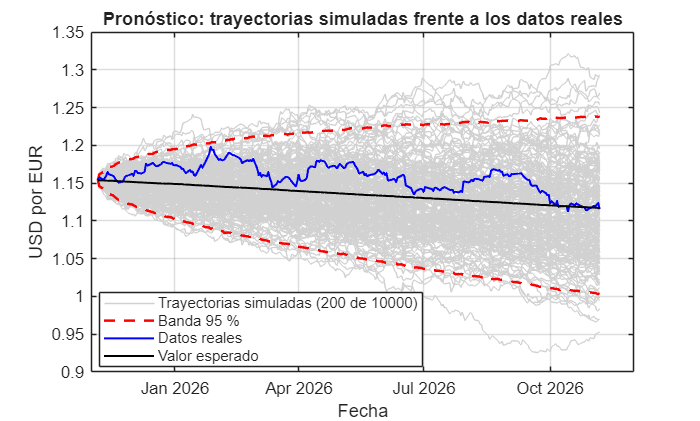

figuraPronostico(X, XS, VECXS, CXSCI, F, cfg, 'simuladas');

## B.4 Verificación con los momentos teóricos

Tm = nRet*dt;
a  = 1 + muest*dt;
Momentos = table(["Teórico, solución exacta"; "Teórico, Euler"; "Simulado (10.000 trayectorias)"; "Dato real X(N)"], ...
    [X(1)*exp(muest*Tm); X(1)*a^nRet; mean(XS(:,N)); X(N)], ...
    [X(1)*exp(muest*Tm)*sqrt(exp(sigmaest^2*Tm) - 1); X(1)*sqrt((a^2 + sigmaest^2*dt)^nRet - a^(2*nRet)); std(XS(:,N)); NaN], ...
    'VariableNames', {'Origen', 'Media_final', 'DesvEst_final'})

Momentos = 4×3 table
                 Origen                 Media_final    DesvEst_final
    ________________________________    ___________    _____________

    "Teórico, solución exacta"            1.1171         0.061094   
    "Teórico, Euler"                      1.1171         0.061101   
    "Simulado (10.000 trayectorias)"       1.117         0.060291   
    "Dato real X(N)"                      1.1154              NaN   


finEuler  = X(1)*prod(1 + muest*dt + sigmaest*sqrt(dt)*Zs, 2);
finExacta = X(1)*exp(sum((muest - sigmaest^2/2)*dt + sigmaest*sqrt(dt)*Zs, 2));
difRel    = 100*abs(finEuler - finExacta)./finExacta;
fprintf('Euler frente a exacta al final del año: diferencia relativa media %.4f %% | máxima %.4f %%n', mean(difRel), max(difRel));

Euler frente a exacta al final del año: diferencia relativa media 0.0106 % | máxima 0.0680 %n

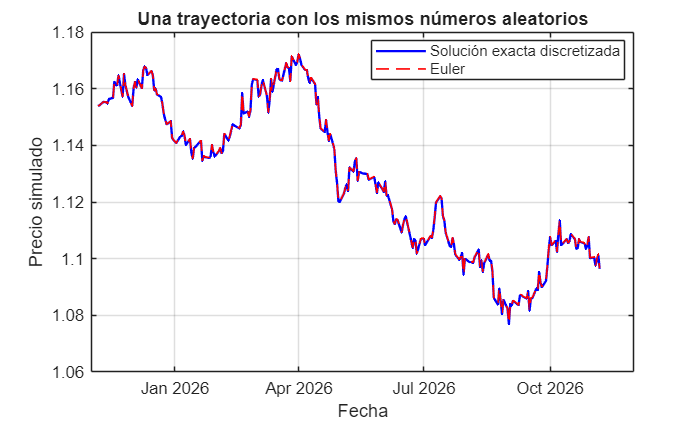

z1 = Zs(1,:);
pEuler  = X(1)*[1, cumprod(1 + muest*dt + sigmaest*sqrt(dt)*z1)];
pExacta = X(1)*[1, exp(cumsum((muest - sigmaest^2/2)*dt + sigmaest*sqrt(dt)*z1))];
figure
plot(F, pExacta, 'b-', 'LineWidth', 1.4); hold on
plot(F, pEuler, 'r--', 'LineWidth', 1.0); hold off; grid on
xlabel('Fecha'); ylabel('Precio simulado')
legend('Solución exacta discretizada', 'Euler', 'Location', 'best')
title('Una trayectoria con los mismos números aleatorios')

## B.5 Resumen de métricas

Meta de la rúbrica: MAPE promedio menor que 5 %.

ResumenPronosticos = [MetricasInducido; MetricasSimulado]

ResumenPronosticos = 2×11 table
    Pronostico    MAPE_min    MAPE_medio    MAPE_max    MAPE_tray_media    MAE_tray_media    RMSE_tray_media    Cobertura_pct    Dias_fuera    Dias_fuera_esperados    R2_tray_media
    __________    ________    __________    ________    _______________    ______________    _______________    _____________    __________    ____________________    _____________

    "Inducido"    0.32009      0.38228      0.45086         0.25574          0.0029595          0.0039934           92.8             18                12.5               0.95238   
    "Simulado"    0.69634       3.3926       13.11

ComparacionConElCurso = table(["Inducido"; "Simulado"], [MetI.MAPE_medio; MetS.MAPE_medio], ...
    [MetI.MAPEcurso_medio; MetS.MAPEcurso_medio], ...
    'VariableNames', {'Pronostico', 'MAPE_medio_propio', 'MAPE_medio_como_el_curso'})

ComparacionConElCurso = 2×3 table
    Pronostico    MAPE_medio_propio    MAPE_medio_como_el_curso
    __________    _________________    ________________________

    "Inducido"         0.38228                 0.38081         
    "Simulado"          3.3926                  3.5056         


fprintf('Meta MAPE < 5 %%: inducido %.4f %% (%s) | simulado %.4f %% (%s)\n', ...
        MetI.MAPE_medio, siNo(MetI.MAPE_medio < 5), MetS.MAPE_medio, siNo(MetS.MAPE_medio < 5));

Meta MAPE < 5 %: inducido 0.3823 % (sí) | simulado 3.3926 % (sí)


# Parte C. Valoración de opciones call europeas

## C.1 Simulación fuera de muestra

$S_0$ = último dato, $\sigma$ histórica, $r = 0.05$, $T = 1, 1/2, 1/3, 1/4$. Los precios de ejercicio salen de 10.000 trayectorias simuladas desde $S_0$ con la deriva estimada; los precios, del mundo neutral al riesgo: $C = e^{-rT}E_Q\left[\max(S_T - K, 0)\right]$.

S0    = X(end);
sigma = sigmaest;
r     = cfg.r;
dias  = round(cfg.Tvec/dt);
nT    = numel(cfg.Tvec);
nK    = numel(cfg.percentiles);
switch cfg.derivaK
    case 'mu', derivaSim = muest;
    case 'r',  derivaSim = r;
end
rng(cfg.semilla);
nDias = max(dias);
Z  = randn(cfg.k, nDias);
XF = zeros(cfg.k, nDias + 1);
XF(:,1) = S0;
for j = 2:nDias+1
    XF(:,j) = XF(:,j-1) .* pasoMBG(derivaSim, sigma, dt, Z(:,j-1), cfg.esquema);
end
mT = S0*exp(derivaSim*cfg.Tvec);
SimulacionFueraDeMuestra = table(cfg.Tvec', dias', mean(XF(:, dias+1))', mT', std(XF(:, dias+1))', ...
    (mT.*sqrt(exp(sigma^2*cfg.Tvec) - 1))', ...
    'VariableNames', {'T', 'Dia', 'Media_simulada', 'Media_teorica', 'Desv_simulada', 'Desv_teorica'})

SimulacionFueraDeMuestra = 4×6 table
       T       Dia    Media_simulada    Media_teorica    Desv_simulada    Desv_teorica
    _______    ___    ______________    _____________    _____________    ____________

          1    252        1.0798           1.0795             0.059         0.059276  
        0.5    126        1.0979           1.0973          0.042468          0.04259  
    0.33333     84        1.1034           1.1033          0.034751          0.03496  
       0.25     63        1.1063           1.1063          0.030556         0.030357  


## C.2 Precios de ejercicio

Percentiles 10, 30, 50, 70 y 90 de $S_T$ simulado en cada vencimiento.

zp   = norminv(cfg.percentiles/100);
Kraw = zeros(nT, nK);  Kteo = zeros(nT, nK);
for i = 1:nT
    Kraw(i,:) = quantile(XF(:, dias(i)+1), cfg.percentiles/100);
    Kteo(i,:) = S0*exp((derivaSim - sigma^2/2)*cfg.Tvec(i) + sigma*sqrt(cfg.Tvec(i))*zp);
end
K = round(Kraw, cfg.decimalesK);
[iT, iK] = ndgrid(1:nT, 1:nK);
iT = reshape(iT', [], 1);  iK = reshape(iK', [], 1);
aCol   = @(M) reshape(M', [], 1);      % matriz 4 x 5 -> columna de 20 opciones
Tcol   = cfg.Tvec(iT)';
Kcol   = aCol(K);
PctCol = cfg.percentiles(iK)';
situ   = repmat("fuera del dinero", numel(Kcol), 1);
situ(Kcol < S0) = "dentro del dinero";
PreciosDeEjercicio = table(Tcol, dias(iT)', PctCol, Kcol, aCol(Kteo), Kcol/S0, situ, ...
    'VariableNames', {'T', 'Dia', 'Percentil', 'K', 'K_teorico', 'K_sobre_S0', 'Situacion'})

PreciosDeEjercicio = 20×7 table
       T       Dia    Percentil      K       K_teorico    K_sobre_S0         Situacion     
    _______    ___    _________    ______    _________    __________    ___________________

          1    252       10        1.0067     1.0047       0.90255      "dentro del dinero"
          1    252       30        1.0474     1.0473       0.93904      "dentro del dinero"
          1    252       50        1.0789     1.0779       0.96728      "dentro del dinero"
          1    252       70        1.1098     1.1094       0.99498      "dentro del dinero"
          1    252       90         1.156     1.1564        1.0364      "fuera del dinero" 
        0.5    126       10        1.0442     1.0433       0.93617      "dentro del d

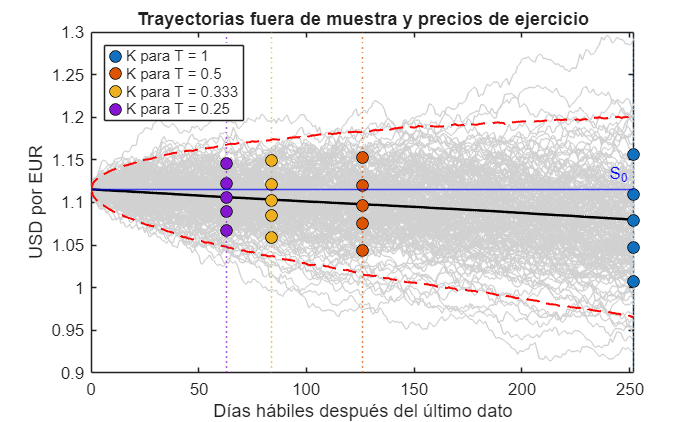

figure
plot(0:nDias, XF(1:cfg.nGraficar,:)', 'Color', [0.82 0.82 0.82]); hold on
plot(0:nDias, mean(XF, 1), 'k', 'LineWidth', 1.5);
plot(0:nDias, quantile(XF, [0.025 0.975], 1)', 'r--', 'LineWidth', 1.2);
colores = lines(nT);
hK = gobjects(nT, 1);
for i = 1:nT
    xline(dias(i), ':', 'Color', colores(i,:));
    hK(i) = plot(repmat(dias(i), 1, nK), K(i,:), 'o', 'MarkerSize', 7, ...
                 'MarkerFaceColor', colores(i,:), 'MarkerEdgeColor', 'k');
end
yline(S0, 'b-', 'S_0'); hold off
xlim([0 nDias]); xlabel('Días hábiles después del último dato'); ylabel('USD por EUR')
title('Trayectorias fuera de muestra y precios de ejercicio')
legend(hK, compose('K para T = %.3g', cfg.Tvec), 'Location', 'northwest')

## C.3 Black-Scholes

$C = S_0 N(d_1) - K e^{-rT} N(d_2)$, validada con el ejemplo del PDF del curso ($S_0 = K = 100$, $\sigma = 0.3$, $T = 1$).

ej = struct('S0', 100, 'K', 100, 'r', 0.05, 'sigma', 0.3, 'T', 1);
[Cej, d1ej, d2ej] = bsCall(ej.S0, ej.K, ej.r, ej.sigma, ej.T);
Pej = bsPut(ej.S0, ej.K, ej.r, ej.sigma, ej.T);
hayBlsprice = exist('blsprice', 'file') == 2;
Cbls = NaN;
if hayBlsprice, Cbls = blsprice(ej.S0, ej.K, ej.r, ej.T, ej.sigma); end
ValidacionBS = table(["Fórmula propia"; "blsprice (NaN si no hay Financial Toolbox)"; "Referencia"; ...
                      "C - P"; "S0 - K*exp(-rT)"], ...
                     [Cej; Cbls; 14.2313; Cej - Pej; ej.S0 - ej.K*exp(-ej.r*ej.T)], ...
                     'VariableNames', {'Concepto', 'Valor'})

ValidacionBS = 5×2 table
                      Concepto                      Valor 
    ____________________________________________    ______

    "Fórmula propia"                                14.231
    "blsprice (NaN si no hay Financial Toolbox)"       NaN
    "Referencia"                                    14.231
    "C - P"                                         4.8771
    "S0 - K*exp(-rT)"                               4.8771


PBS = NaN(nT, nK);  ND2 = NaN(nT, nK);  tBS = NaN(nT, nK);
for i = 1:nT
    for j = 1:nK
        tic
        [PBS(i,j), ~, d2] = bsCall(S0, K(i,j), r, sigma, cfg.Tvec(i));
        tBS(i,j) = toc;
        ND2(i,j) = normcdf(d2);
    end
end
PreciosBS = table(Tcol, Kcol, aCol(PBS), aCol(ND2), 'VariableNames', {'T', 'K', 'Precio_BS', 'Prob_ejercicio_Q'})

PreciosBS = 20×4 table
       T         K       Precio_BS    Prob_ejercicio_Q
    _______    ______    _________    ________________

          1    1.0067      0.15784        0.99704     
          1    1.0474       0.1195        0.97883     
          1    1.0789     0.090771        0.93191     
          1    1.1098     0.064657        0.83536     
          1     1.156     0.032942        0.59182     
        0.5    1.0442     0.097114        0.98997     
        0.5    1.0749      0.06802        0.94274     
        0.5    1.0969     0.048634        0.85453     
        0.5    1.1195     0.031369        0.70208     
        0.5    1.1527     0.013269        0.41182     
    0.33333    1.0593     0.073798        0.98379     
    0.33333    1.0847     0.049876        0.91793     
    0.33333    1.1024     0.034744        0.81067     
    0.33333    

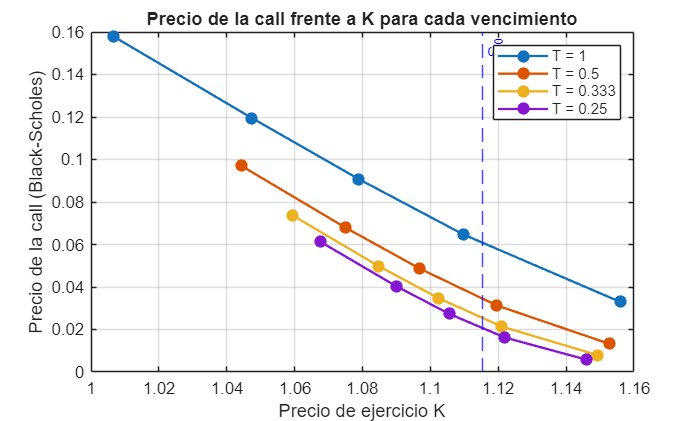

figure
hold on
for i = 1:nT
    plot(K(i,:), PBS(i,:), '-o', 'Color', colores(i,:), 'LineWidth', 1.4, 'MarkerFaceColor', colores(i,:));
end
xline(S0, 'b--', 'S_0'); hold off; box on; grid on
xlabel('Precio de ejercicio K'); ylabel('Precio de la call (Black-Scholes)')
title('Precio de la call frente a K para cada vencimiento')
legend(compose('T = %.3g', cfg.Tvec), 'Location', 'northeast')

## C.4 Árbol binomial

Código del PDF del curso con $n = 1000$ y $p = 1/2 + (r - \sigma^2/2)\sqrt{\Delta t}/(2\sigma)$.

nB = cfg.nBin;
tic; VejCurso = binomialCurso(ej.S0, ej.K, ej.r, ej.sigma, ej.T, nB, cfg.tipoP); tEjCurso = toc;
VejVec = binomialVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, nB, cfg.tipoP);
VejCRR = binomialVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, nB, 'crr');
ValidacionBinomial = table(["Código del curso"; "Vectorizado"; "p exacta (CRR)"; "Black-Scholes"], ...
    [VejCurso; VejVec; VejCRR; Cej], 100*abs([VejCurso; VejVec; VejCRR; Cej] - Cej)/Cej, ...
    'VariableNames', {'Concepto', 'Precio', 'ErrRel_pct'})

ValidacionBinomial = 4×3 table
         Concepto         Precio    ErrRel_pct
    __________________    ______    __________

    "Código del curso"    14.228     0.021067 
    "Vectorizado"         14.228     0.021067 
    "p exacta (CRR)"      14.228     0.020699 
    "Black-Scholes"       14.231            0 


PBin = NaN(nT, nK);  tBin = NaN(nT, nK);
for i = 1:nT
    for j = 1:nK
        tic
        PBin(i,j) = binomialCurso(S0, K(i,j), r, sigma, cfg.Tvec(i), nB, cfg.tipoP);
        tBin(i,j) = toc;
    end
end
EBin = 100*abs(PBin - PBS)./PBS;
fprintf('Binomial, 20 opciones: error relativo entre %.4f %% y %.4f %% | tiempo total %.2f s\n', ...
        min(EBin(:)), max(EBin(:)), sum(tBin(:)));

Binomial, 20 opciones: error relativo entre 0.0002 % y 0.0486 % | tiempo total 3.86 s


[~, iPeor] = max(EBin(:));
[iTp, iKp] = ind2sub(size(EBin), iPeor);
nConv = cfg.nConv;
errEj = zeros(size(nConv));  errPeor = zeros(size(nConv));
for m = 1:numel(nConv)
    errEj(m)   = 100*abs(binomialVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, nConv(m), cfg.tipoP) - Cej)/Cej;
    errPeor(m) = 100*abs(binomialVec(S0, K(iTp,iKp), r, sigma, cfg.Tvec(iTp), nConv(m), cfg.tipoP) ...
                 - PBS(iTp,iKp))/PBS(iTp,iKp);
end
ConvergenciaBinomial = table(nConv', errEj', errPeor', 'VariableNames', {'n', 'ErrRel_ejemplo_pct', 'ErrRel_peor_opcion_pct'})

ConvergenciaBinomial = 8×3 table
     n      ErrRel_ejemplo_pct    ErrRel_peor_opcion_pct
    ____    __________________    ______________________

      25          0.76035                  1.4739       
      50          0.42031                 0.13586       
     100          0.21043                 0.10542       
     200          0.10528                0.024738       
     400         0.052657               0.0030762       
     800         0.026332               0.0083588       
    1000         0.021067                0.048638       
    2000         0.010534                0.028216       


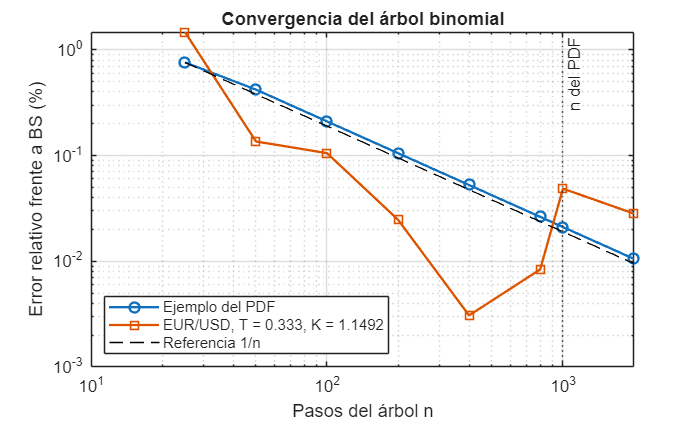

figure
loglog(nConv, errEj, '-o', 'LineWidth', 1.4); hold on
loglog(nConv, errPeor, '-s', 'LineWidth', 1.4);
loglog(nConv, errEj(1)*nConv(1)./nConv, 'k--');
xline(nB, ':', 'n del PDF'); hold off; grid on
xlabel('Pasos del árbol n'); ylabel('Error relativo frente a BS (%)')
legend('Ejemplo del PDF', sprintf('EUR/USD, T = %.3g, K = %.4f', cfg.Tvec(iTp), K(iTp,iKp)), ...
       'Referencia 1/n', 'Location', 'southwest')
title('Convergencia del árbol binomial')

## C.5 Monte Carlo

Solución exacta en un paso con deriva $r$, $W = 1000$ repeticiones de $k = 10000$ trayectorias; error estándar e intervalo del 95 %.

rng(cfg.semilla + 1);
tic; Mcurso = mcCurso(ej.S0, ej.K, ej.r, ej.sigma, ej.T, cfg.WCurso, cfg.kMC, cfg.mMC); tMcCurso = toc;
tic; Mej    = mcExacta(ej.S0, ej.K, ej.r, ej.sigma, ej.T, cfg.W, cfg.kMC, false);      tMcEj = toc;
Mant = mcExacta(ej.S0, ej.K, ej.r, ej.sigma, ej.T, cfg.W, cfg.kMC, true);
seEj = std(Mej)/sqrt(cfg.W);
ValidacionMonteCarlo = table(["Curso: Euler, 200 pasos, W = 10"; "Solución exacta, W = 1000"; ...
                              "Antitéticas, W = 1000"; "Black-Scholes"], ...
    [mean(Mcurso); mean(Mej); mean(Mant); Cej], ...
    [std(Mcurso)/sqrt(cfg.WCurso); seEj; std(Mant)/sqrt(cfg.W); 0], [tMcCurso; tMcEj; NaN; NaN], ...
    'VariableNames', {'Concepto', 'Precio', 'Error_estandar', 'Tiempo_s'})

ValidacionMonteCarlo = 4×4 table
                Concepto                 Precio    Error_estandar    Tiempo_s
    _________________________________    ______    ______________    ________

    "Curso: Euler, 200 pasos, W = 10"    14.178        0.10447       0.68252 
    "Solución exacta, W = 1000"          14.248      0.0070542       0.28064 
    "Antitéticas, W = 1000"              14.221      0.0055412           NaN 
    "Black-Scholes"                      14.231              0           NaN 


zEj = (mean(Mej) - Cej)/seEj;
fprintf('Ejemplo: distancia a BS = %.2f errores estándar (probabilidad de una distancia así o mayor si el método es correcto: %.4f)\n', ...
        zEj, 2*(1 - normcdf(abs(zEj))));

Ejemplo: distancia a BS = 2.39 errores estándar (probabilidad de una distancia así o mayor si el método es correcto: 0.0168)


fprintf('El código del curso con W = 1000 tardaría unos %.0f s por opción.\n', tMcCurso*cfg.W/cfg.WCurso);

El código del curso con W = 1000 tardaría unos 68 s por opción.


PMC = NaN(nT, nK);  seMC = NaN(nT, nK);  se1MC = NaN(nT, nK);  tMC = NaN(nT, nK);
for i = 1:nT
    for j = 1:nK
        tic
        M = mcExacta(S0, K(i,j), r, sigma, cfg.Tvec(i), cfg.W, cfg.kMC, false);
        tMC(i,j)   = toc;
        PMC(i,j)   = mean(M);
        seMC(i,j)  = std(M)/sqrt(cfg.W);
        se1MC(i,j) = std(M);
    end
end
dentroIC = abs(PMC - PBS) <= 1.96*seMC;
DetalleMonteCarlo = table(Tcol, Kcol, aCol(PBS), aCol(PMC), aCol(seMC), aCol(dentroIC), ...
    aCol(100*abs(PMC - PBS)./PBS), aCol(100*se1MC./PBS), ...
    'VariableNames', {'T', 'K', 'BS', 'MC', 'EE', 'BS_en_IC95', 'ErrRel_pct', 'EE_rel_una_corrida_pct'})

DetalleMonteCarlo = 20×8 table
       T         K          BS           MC            EE        BS_en_IC95    ErrRel_pct    EE_rel_una_corrida_pct
    _______    ______    _________    _________    __________    __________    __________    ______________________

          1    1.0067      0.15784      0.15782     1.884e-05      true          0.016451           0.37744        
          1    1.0474       0.1195      0.11951    1.9529e-05      true         0.0069579           0.51677        
          1    1.0789     0.090771     0.090752    1.8574e-05      true          0.020742           0.64708        
          1    1.1098     0.064657     0.064626    1.6492e-05      true          0.047252           0.80662        


fprintf('Black-Scholes dentro del IC del 95 %% en %d de 20 opciones | tiempo total %.2f s\n', sum(dentroIC(:)), sum(tMC(:)));

Black-Scholes dentro del IC del 95 % en 20 de 20 opciones | tiempo total 4.07 s


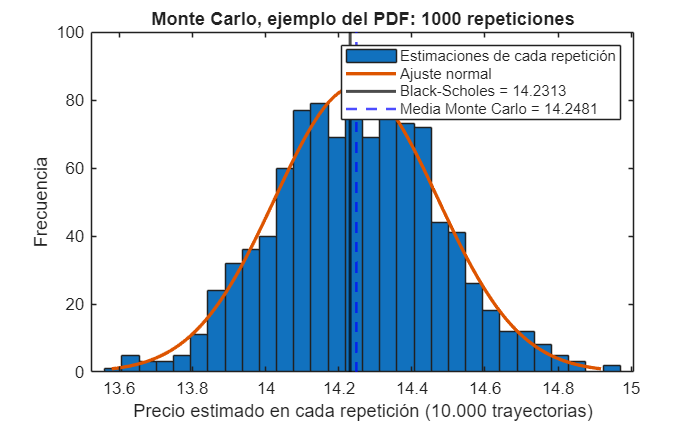

figure
h19 = histfit(Mej, 30);
hBS = xline(Cej, 'k-', 'LineWidth', 1.8);
hMC = xline(mean(Mej), 'b--', 'LineWidth', 1.5);
legend([h19(1) h19(2) hBS hMC], {'Estimaciones de cada repetición', 'Ajuste normal', ...
       sprintf('Black-Scholes = %.4f', Cej), sprintf('Media Monte Carlo = %.4f', mean(Mej))}, 'Location', 'northeast')
xlabel('Precio estimado en cada repetición (10.000 trayectorias)'); ylabel('Frecuencia')
title('Monte Carlo, ejemplo del PDF: 1000 repeticiones')

## C.6 Diferencias finitas explícitas

Código del PDF del curso con $S_{max} = 2K$ y $\Delta t$ en el límite de estabilidad; para el EUR/USD, $\Delta S = S_0/800$ para que $S_0$ sea un nodo de la malla.

[VdfCurso, MOej] = dfCurso(ej.S0, ej.K, ej.r, ej.sigma, ej.T, 2*ej.K, 10);
VdfVec = dfVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, 2*ej.K, 10, 1);
fprintf('Ejemplo, código del curso (dS = 10, Smax = 200): %.6f (error %.4f %%, malla %d x %d) | vectorizado: %.6f\n', ...
        VdfCurso, 100*abs(VdfCurso - Cej)/Cej, size(MOej, 1), size(MOej, 2), VdfVec);

Ejemplo, código del curso (dS = 10, Smax = 200): 14.084539 (error 1.0309 %, malla 37 x 21) | vectorizado: 14.084539


dsEj = cfg.dsEj;
err2K = zeros(size(dsEj));  err3S = zeros(size(dsEj));
for m = 1:numel(dsEj)
    err2K(m) = 100*abs(dfVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, 2*ej.K,  dsEj(m), 1) - Cej)/Cej;
    err3S(m) = 100*abs(dfVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, 3*ej.S0, dsEj(m), 1) - Cej)/Cej;
end
RefinamientoEjemplo = table(dsEj', err2K', err3S', 'VariableNames', {'dS', 'ErrRel_Smax_2K_pct', 'ErrRel_Smax_3S0_pct'})

RefinamientoEjemplo = 5×3 table
    dS     ErrRel_Smax_2K_pct    ErrRel_Smax_3S0_pct
    ___    __________________    ___________________

     10          1.0309                  1.0304     
      5         0.37271                 0.25499     
      2         0.19059                0.041496     
      1         0.16465                 0.01112     
    0.5         0.15816               0.0035303     


precioEst = zeros(size(cfg.factoresEst));  minBEst = zeros(size(cfg.factoresEst));
for m = 1:numel(cfg.factoresEst)
    [precioEst(m), infE] = dfVec(ej.S0, ej.K, ej.r, ej.sigma, ej.T, 2*ej.K, cfg.dsInestable, cfg.factoresEst(m));
    minBEst(m) = infE.minB;
end
Estabilidad = table(cfg.factoresEst', minBEst', precioEst', ...
    'VariableNames', {'dt_sobre_limite', 'min_b_j', 'Precio'})

Estabilidad = 4×3 table
    dt_sobre_limite     min_b_j       Precio   
    _______________    _________    ___________

            1                  0         14.204
         1.05          -0.048948         14.204
          1.2           -0.19999     5.9021e+11
          1.5           -0.49996    3.2071e+102


dsEU = S0/cfg.nS0;
PDF = NaN(nT, nK);  tDF = NaN(nT, nK);  minB = NaN(nT, nK);
for i = 1:nT
    for j = 1:nK
        SmaxIJ = ceil(cfg.SmaxFactorK*K(i,j)/dsEU)*dsEU;
        tic
        [PDF(i,j), infDF] = dfVec(S0, K(i,j), r, sigma, cfg.Tvec(i), SmaxIJ, dsEU, 1);
        tDF(i,j)  = toc;
        minB(i,j) = infDF.minB;
    end
end
EDF = 100*abs(PDF - PBS)./PBS;
fprintf('Dif. finitas, 20 opciones (dS = %.6f): error entre %.4f %% y %.4f %% | mínimo b_j = %.2e | tiempo %.2f s\n', ...
        dsEU, min(EDF(:)), max(EDF(:)), min(minB(:)), sum(tDF(:)));

Dif. finitas, 20 opciones (dS = 0.001394): error entre 0.0002 % y 0.0199 % | mínimo b_j = 5.34e-06 | tiempo 3.73 s


[~, iPeorDF] = max(EDF(:));
[iTd, iKd] = ind2sub(size(EDF), iPeorDF);
nS0c = cfg.nS0Conv;
errDFc = zeros(size(nS0c));
for m = 1:numel(nS0c)
    dsm = S0/nS0c(m);
    errDFc(m) = 100*abs(dfVec(S0, K(iTd,iKd), r, sigma, cfg.Tvec(iTd), ceil(cfg.SmaxFactorK*K(iTd,iKd)/dsm)*dsm, dsm, 1) ...
                - PBS(iTd,iKd))/PBS(iTd,iKd);
end
ConvergenciaDifFinitas = table(nS0c', (S0./nS0c)', errDFc', 'VariableNames', {'nS0', 'dS', 'ErrRel_pct'})

ConvergenciaDifFinitas = 5×3 table
    nS0         dS        ErrRel_pct
    ____    __________    __________

     100      0.011154      0.18769 
     200      0.005577     0.084303 
     400     0.0027885      0.11609 
     800     0.0013942     0.019947 
    1600    0.00069712    0.0014879 


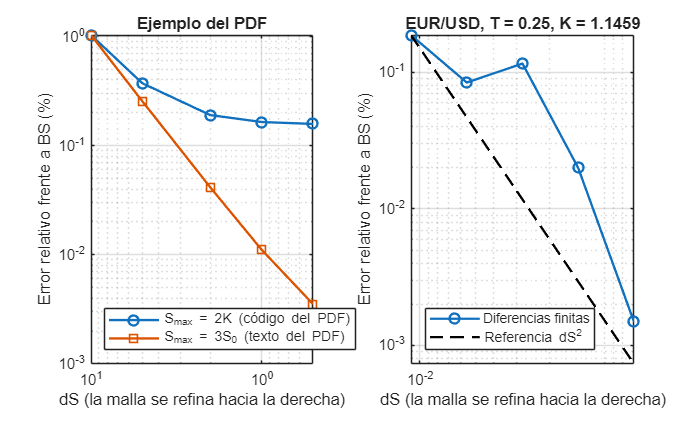

figure
tiledlayout(1, 2)
nexttile
loglog(dsEj, err2K, '-o', dsEj, err3S, '-s', 'LineWidth', 1.4); grid on; set(gca, 'XDir', 'reverse')
xlabel('dS (la malla se refina hacia la derecha)'); ylabel('Error relativo frente a BS (%)')
legend('S_{max} = 2K (código del PDF)', 'S_{max} = 3S_0 (texto del PDF)', 'Location', 'southwest')
title('Ejemplo del PDF')
nexttile
dsc = S0./nS0c;
loglog(dsc, errDFc, '-o', dsc, errDFc(1)*(dsc/dsc(1)).^2, 'k--', 'LineWidth', 1.4); grid on; set(gca, 'XDir', 'reverse')
xlabel('dS (la malla se refina hacia la derecha)'); ylabel('Error relativo frente a BS (%)')
legend('Diferencias finitas', 'Referencia dS^2', 'Location', 'southwest')
title(sprintf('EUR/USD, T = %.3g, K = %.4f', cfg.Tvec(iTd), K(iTd,iKd)))

# Comparación con Black-Scholes

Error relativo: $100\,|P_{metodo} - P_{BS}|/P_{BS}$.

EMC = 100*abs(PMC - PBS)./PBS;
Comparacion = table(Tcol, Kcol, PctCol, aCol(PBS), aCol(PBin), aCol(EBin), aCol(PMC), aCol(EMC), aCol(PDF), aCol(EDF), ...
    'VariableNames', {'T', 'K', 'Percentil', 'BS', 'Binomial', 'ErrRel_Bin_pct', ...
                      'MonteCarlo', 'ErrRel_MC_pct', 'DifFinitas', 'ErrRel_DF_pct'});
ComparacionT1    = Comparacion(Tcol == cfg.Tvec(1), :)

ComparacionT1 = 5×10 table
    T      K       Percentil       BS       Binomial    ErrRel_Bin_pct    MonteCarlo    ErrRel_MC_pct    DifFinitas    ErrRel_DF_pct
    _    ______    _________    ________    ________    ______________    __________    _____________    __________    _____________

    1    1.0067       10         0.15784     0.15784      0.00085374        0.15782        0.016451        0.15784      0.00015594  
    1    1.0474       30          0.1195      0.1195       0.0015392        0.11951       0.0069579         0.1195      0.00032816  
    1    1.0789       50        0.090771     0.09077      0.00067155       0.090752        0.020742 

ComparacionT1_2  = Comparacion(Tcol == cfg.Tvec(2), :)

ComparacionT1_2 = 5×10 table
     T       K       Percentil       BS       Binomial    ErrRel_Bin_pct    MonteCarlo    ErrRel_MC_pct    DifFinitas    ErrRel_DF_pct
    ___    ______    _________    ________    ________    ______________    __________    _____________    __________    _____________

    0.5    1.0442       10        0.097114    0.097114      0.00056085       0.097109       0.0051986       0.097114       0.0002418  
    0.5    1.0749       30         0.06802    0.068019       0.0018229       0.068017       0.0041034       0.068019        0.001157  
    0.5    1.0969       50        0.048634    0.048634      0.00096438       0.048635     

ComparacionT1_3  = Comparacion(Tcol == cfg.Tvec(3), :)

ComparacionT1_3 = 5×10 table
       T         K       Percentil       BS        Binomial     ErrRel_Bin_pct    MonteCarlo    ErrRel_MC_pct    DifFinitas    ErrRel_DF_pct
    _______    ______    _________    _________    _________    ______________    __________    _____________    __________    _____________

    0.33333    1.0593       10         0.073798     0.073798      0.00024065       0.073792       0.0086782       0.073798      0.00018741  
    0.33333    1.0847       30         0.049876     0.049875       0.0020623       0.049864          0.0231       0.049875        0.002241  
    0.33333    1.1024       50         0.034744     0.034743      

ComparacionT1_4  = Comparacion(Tcol == cfg.Tvec(4), :)

ComparacionT1_4 = 5×10 table
     T        K       Percentil       BS       Binomial     ErrRel_Bin_pct    MonteCarlo    ErrRel_MC_pct    DifFinitas    ErrRel_DF_pct
    ____    ______    _________    ________    _________    ______________    __________    _____________    __________    _____________

    0.25    1.0677       10        0.061185     0.061184      0.00035952       0.061171        0.022749       0.061184      0.00023201  
    0.25    1.0899       30        0.040411     0.040412       0.0015992       0.040409       0.0056139       0.040411      0.00071638  
    0.25    1.1056       50        0.027321      0.02732        0.004522       0.0

ResumenPorMetodo = table(["Black-Scholes"; "Árbol binomial (n = 1000)"; "Monte Carlo (1000 x 10000)"; ...
                          "Diferencias finitas (dS = S0/800)"], ...
    [0; mean(EBin(:)); mean(EMC(:)); mean(EDF(:))], [0; max(EBin(:)); max(EMC(:)); max(EDF(:))], ...
    [sum(tBS(:)); sum(tBin(:)); sum(tMC(:)); sum(tDF(:))], ...
    'VariableNames', {'Metodo', 'ErrRel_medio_pct', 'ErrRel_max_pct', 'Tiempo_total_s'})

ResumenPorMetodo = 4×4 table
                  Metodo                   ErrRel_medio_pct    ErrRel_max_pct    Tiempo_total_s
    ___________________________________    ________________    ______________    ______________

    "Black-Scholes"                                   0                  0         0.0081184   
    "Árbol binomial (n = 1000)"               0.0057798           0.048638            3.8601   
    "Monte Carlo (1000 x 10000)"               0.016774           0.058582            4.0733   
    "Diferencias finitas (dS = S0/800)"       0.0038781           0.019947            3.7346   


# Conclusiones

- Los datos son consistentes con un MBG salvo por la normalidad (colas pesadas).

- Los dos pronósticos cumplen la meta de MAPE menor que 5 %.

- Los tres métodos numéricos reproducen Black-Scholes con errores por debajo del 0.1 %. El binomial y las diferencias finitas tienen error de discretización; Monte Carlo, error de muestreo.

- El error del binomial baja como $1/n$, el de Monte Carlo como $1/\sqrt{M}$ y el de diferencias finitas como $\Delta S^2$.

- El precio de la call baja con $K$ y sube con $T$; las opciones más baratas tienen el mayor error relativo.

## Funciones locales

function tb = bateriaPruebas(r, dt, alpha, rez)
% Batería de pruebas del script del curso sobre un vector de retornos r.
    r  = r(:);
    Z  = (r - mean(r))/std(r);
    [hJB, pJB, eJB] = jbtest(r, alpha);
    [hKS, pKS, eKS] = kstest(Z, 'Alpha', alpha);
    [hAD, pAD, eAD] = adtest(r, 'Alpha', alpha);
    [hLI, pLI, eLI] = lillietest(r, 'Alpha', alpha);
    Et  = (r - mean(r))/sqrt(dt);
    [hADF, pADF, eADF] = adftest(Et, 'Alpha', alpha);
    [hAR,  pAR,  eAR ] = archtest(Et, 'Lags', rez, 'Alpha', alpha);
    [hLB2, pLB2, eLB2] = lbqtest(Et.^2, 'Lags', rez, 'Alpha', alpha);
    [hLB,  pLB,  eLB ] = lbqtest(r, 'Lags', rez, 'Alpha', alpha);
    Prueba = ["Jarque-Bera"; "Kolmogorov-Smirnov sobre Z"; "Anderson-Darling"; "Lilliefors"; ...
              "ADF sobre Et"; "ARCH de Engle sobre Et"; "Ljung-Box sobre Et^2"; "Ljung-Box sobre retornos"];
    Condicion = ["Normalidad"; "Normalidad"; "Normalidad"; "Normalidad"; "Estacionariedad"; ...
                 "Varianza constante"; "Varianza constante"; "Independencia"];
    H0 = ["Normal"; "Z ~ N(0,1)"; "Normal"; "Normal"; "Raíz unitaria"; "Sin efecto ARCH"; ...
          "Sin autocorrelación"; "Sin autocorrelación"];
    h           = double([hJB; hKS; hAD; hLI; hADF; hAR; hLB2; hLB]);
    ValorP      = [pJB; pKS; pAD; pLI; pADF; pAR; pLB2; pLB];
    Estadistico = [eJB; eKS; eAD; eLI; eADF; eAR; eLB2; eLB];
    hDeseado    = [0; 0; 0; 0; 1; 0; 0; 0];      % en la ADF se desea rechazar H0
    Cumple      = h == hDeseado;
    tb = table(Prueba, Condicion, H0, h, ValorP, Estadistico, hDeseado, Cumple);
end
function C = tablaCondiciones(tb, hayAlertaSalto, zMax, aporte2, EH, sEH)
% Resume la batería por condición del MBG.
    esFiable  = tb.Condicion == "Normalidad" & tb.Prueba ~= "Kolmogorov-Smirnov sobre Z";
    nRechazan = sum(~tb.Cumple(esFiable));
    p = @(nombre) tb.ValorP(tb.Prueba == nombre);
    Condicion = ["Estacionariedad"; "Independencia"; "Varianza constante"; "Normalidad"; ...
                 "Sin saltos"; "Carácter browniano (Hurst)"];
    Cumple = [all(tb.Cumple(tb.Condicion == "Estacionariedad")); all(tb.Cumple(tb.Condicion == "Independencia")); ...
              all(tb.Cumple(tb.Condicion == "Varianza constante")); nRechazan == 0; ~hayAlertaSalto; ...
              abs(EH - 0.5) <= 2*sEH];
    Evidencia = [string(sprintf('ADF: p = %.4f (aquí se desea rechazar)', p("ADF sobre Et"))); ...
                 string(sprintf('Ljung-Box sobre retornos: p = %.4f', p("Ljung-Box sobre retornos"))); ...
                 string(sprintf('ARCH: p = %.4f; Ljung-Box sobre Et^2: p = %.4f', p("ARCH de Engle sobre Et"), p("Ljung-Box sobre Et^2"))); ...
                 string(sprintf('Rechazan %d de 3 pruebas fiables; KS sobre Z: p = %.4f', nRechazan, p("Kolmogorov-Smirnov sobre Z"))); ...
                 string(sprintf('Mayor movimiento %.1f desv. est.; 2 días = %.1f %% de la varianza', zMax, aporte2)); ...
                 string(sprintf('H = %.3f, a %.1f desv. est. de 0.5', EH, abs(EH - 0.5)/sEH))];
    C = table(Condicion, Cumple, Evidencia);
end
function fac = pasoMBG(mu, sigma, dt, Z, esquema)
% Factor multiplicativo de un paso del MBG: X_nuevo = X_anterior .* fac
    switch esquema
        case 'euler',  fac = 1 + mu*dt + sigma*sqrt(dt).*Z;
        case 'exacta', fac = exp((mu - sigma^2/2)*dt + sigma*sqrt(dt).*Z);
    end
end
function [M, media, banda] = metricas(X, XP, nivel)
% Precisión y ajuste de un pronóstico XP (k x N) frente a los datos X (1 x N), días 2..N.
    a     = (1 - nivel)/2;
    media = mean(XP, 1);
    banda = quantile(XP, [a 1-a], 1);
    A  = X(2:end);  P = XP(:, 2:end);  Pm = media(2:end);
    mapeTray = 100*mean(abs(A - P)./abs(A), 2);
    M.MAPE_min   = min(mapeTray);
    M.MAPE_medio = mean(mapeTray);
    M.MAPE_max   = max(mapeTray);
    M.MAPE_media = 100*mean(abs(A - Pm)./abs(A));
    M.MAE_media  = mean(abs(A - Pm));
    M.RMSE_media = sqrt(mean((A - Pm).^2));
    dentro = A >= banda(1,2:end) & A <= banda(2,2:end);
    M.Cobertura_pct = 100*mean(dentro);
    M.DiasFuera     = sum(~dentro);
    c = corrcoef(A, Pm);
    M.R2_tray_media = c(1,2)^2;
    Ac = A - mean(A);  Pc = P - mean(P, 2);
    rTray = (Pc*Ac.')./(sqrt(sum(Pc.^2, 2))*sqrt(sum(Ac.^2)));
    M.R2_medio = mean(rTray.^2);
    M.MAPEcurso_medio = mean(100*mean(abs(XP - X)./abs(XP), 2));   % como mape(X, XI') del curso
end
function t = tablaMetricas(nombre, M, nivel, nRet)
% Una fila con las métricas de precisión y ajuste de un pronóstico.
    t = table(nombre, M.MAPE_min, M.MAPE_medio, M.MAPE_max, M.MAPE_media, M.MAE_media, M.RMSE_media, ...
              M.Cobertura_pct, M.DiasFuera, (1 - nivel)*nRet, M.R2_tray_media, ...
              'VariableNames', {'Pronostico', 'MAPE_min', 'MAPE_medio', 'MAPE_max', 'MAPE_tray_media', ...
                                'MAE_tray_media', 'RMSE_tray_media', 'Cobertura_pct', 'Dias_fuera', ...
                                'Dias_fuera_esperados', 'R2_tray_media'});
end
function figuraPronostico(X, XP, media, banda, F, cfg, tipo)
    nG = min(cfg.nGraficar, size(XP, 1));
    figure
    h1 = plot(F, XP(1:nG,:)', 'Color', 0.82*ones(1,3)); hold on
    h2 = plot(F, banda', 'r--', 'LineWidth', 1.5);
    h3 = plot(F, X, 'b', 'LineWidth', 1.2);
    h4 = plot(F, media, 'k', 'LineWidth', 1.2); hold off; grid on
    xlabel('Fecha'); ylabel('USD por EUR')
    title(sprintf('Pronóstico: trayectorias %s frente a los datos reales', tipo))
    legend([h1(1) h2(1) h3 h4], {sprintf('Trayectorias %s (%d de %d)', tipo, nG, size(XP,1)), ...
           sprintf('Banda %.0f %%', 100*cfg.nivelBanda), 'Datos reales', 'Valor esperado'}, 'Location', 'best')
end
function [C, d1, d2] = bsCall(S0, K, r, sigma, T)
% Call europea con la fórmula de Black-Scholes (PDF del curso).
    d1 = (log(S0./K) + (r + sigma.^2/2).*T)./(sigma.*sqrt(T));
    d2 = d1 - sigma.*sqrt(T);
    C  = S0.*normcdf(d1) - K.*exp(-r.*T).*normcdf(d2);
end
function Pp = bsPut(S0, K, r, sigma, T)
% Put europea con Black-Scholes (solo para la paridad put-call).
    d1 = (log(S0./K) + (r + sigma.^2/2).*T)./(sigma.*sqrt(T));
    d2 = d1 - sigma.*sqrt(T);
    Pp = K.*exp(-r.*T).*normcdf(-d2) - S0.*normcdf(-d1);
end
function p = probBinomial(r, sigma, dt, tipoP)
% Probabilidad neutral al riesgo de subir en el árbol.
    switch tipoP
        case 'curso', p = 1/2 + 1/(2*sigma)*(r - 1/2*sigma^2)*sqrt(dt);
        case 'crr'
            u = exp(sigma*sqrt(dt));  d = 1/u;
            p = (exp(r*dt) - d)/(u - d);
    end
end
function V = binomialCurso(S0, K, r, sigma, T, n, tipoP)
% Árbol binomial: mismo código del PDF del curso (pág. 8), con matrices completas.
    dt = T/n;  u = exp(sigma*sqrt(dt));  d = 1/u;  a = exp(-r*dt);
    p  = probBinomial(r, sigma, dt, tipoP);
    SF  = zeros(n+1, n+1);
    Opt = zeros(n+1, n+1);
    for i = 1:n+1
        for j = 1:i
            SF(i,j) = S0*u^(j-1)*d^(i-j);
        end
    end
    for j = 1:n+1
        Opt(n+1,j) = max(SF(n+1,j) - K, 0);
    end
    for i = n:-1:1
        for j = 1:i
            Opt(i,j) = a*((1-p)*Opt(i+1,j) + p*Opt(i+1,j+1));
        end
    end
    V = Opt(1,1);
end
function V = binomialVec(S0, K, r, sigma, T, n, tipoP)
% Mismo árbol, guardando solo un vector y calculando cada paso de una vez.
    dt = T/n;  u = exp(sigma*sqrt(dt));  d = 1/u;  a = exp(-r*dt);
    p  = probBinomial(r, sigma, dt, tipoP);
    j  = (0:n)';
    V  = max(S0*u.^j.*d.^(n-j) - K, 0);
    for i = n:-1:1
        V = a*((1-p)*V(1:i) + p*V(2:i+1));
    end
end
function M1 = mcCurso(S0, K, r, sigma, T, W, k, m)
% Monte Carlo: mismo código del PDF del curso (pág. 4), Euler con m pasos y bucles.
    dt = T/m;
    M1 = zeros(W, 1);  S1 = zeros(k, m+1);  f1 = zeros(k, 1);
    for n = 1:W
        rn = randn(k, m);
        for i = 1:k
            S1(i,1) = S0;
        end
        for i = 1:k
            for j = 2:m+1
                S1(i,j) = S1(i,j-1) + r*S1(i,j-1)*dt + sigma*S1(i,j-1)*sqrt(dt)*rn(i,j-1);
            end
        end
        for i = 1:k
            f1(i) = exp(-r*T)*max(S1(i,m+1) - K, 0);
        end
        M1(n) = mean(f1);
    end
end
function M = mcExacta(S0, K, r, sigma, T, W, k, antiteticas)
% Monte Carlo con la solución exacta en un paso; opcionalmente con variables antitéticas.
    M = zeros(W, 1);
    a = (r - sigma^2/2)*T;  b = sigma*sqrt(T);  desc = exp(-r*T);
    for n = 1:W
        if antiteticas
            e = randn(k/2, 1);  e = [e; -e];
        else
            e = randn(k, 1);
        end
        M(n) = desc*mean(max(S0*exp(a + b*e) - K, 0));
    end
end
function [V, MO] = dfCurso(S0, K, r, sigma, T, Smax, ds)
% Diferencias finitas explícitas: mismo código del PDF del curso (pág. 13), malla completa.
    ns  = round(Smax/ds);
    dtp = (ds/(sigma*Smax))^2;
    nt  = ceil(T/dtp);
    dt  = T/nt;
    S = zeros(1, ns+1);
    for j = 2:ns+1
        S(j) = S(j-1) + ds;
    end
    MO = zeros(nt+1, ns+1);
    MO(:, ns+1) = Smax - K;
    for j = 1:ns
        MO(nt+1, j) = max(S(j) - K, 0);
    end
    a = zeros(1, ns+1);  b = a;  c = a;
    for j = 1:ns+1
        a(j) = (dt/(1+r*dt))*((-1/2)*r*(j-1) + (1/2)*sigma^2*(j-1)^2);
        b(j) = (dt/(1+r*dt))*((1/dt) - sigma^2*(j-1)^2);
        c(j) = (dt/(1+r*dt))*((1/2)*r*(j-1) + (1/2)*sigma^2*(j-1)^2);
    end
    for i = nt:-1:1
        for j = 2:ns
            MO(i,j) = a(j)*MO(i+1,j-1) + b(j)*MO(i+1,j) + c(j)*MO(i+1,j+1);
        end
    end
    V = MO(1, round(S0/ds) + 1);
end
function [V, info] = dfVec(S0, K, r, sigma, T, Smax, ds, factorDt)
% Mismo esquema guardando solo la fila de tiempo actual; factorDt > 1 viola la estabilidad.
    ns  = round(Smax/ds);
    nt  = ceil(T/(factorDt*(ds/(sigma*Smax))^2));
    dt  = T/nt;
    jj  = 0:ns;
    f   = dt/(1+r*dt);
    a = f*(-r*jj/2 + sigma^2*jj.^2/2);
    b = f*(1/dt - sigma^2*jj.^2);
    c = f*( r*jj/2 + sigma^2*jj.^2/2);
    V = max(jj*ds - K, 0);  V(end) = Smax - K;
    in = 2:ns;
    for i = 1:nt
        V(in) = a(in).*V(in-1) + b(in).*V(in) + c(in).*V(in+1);
    end
    V = V(round(S0/ds) + 1);
    info = struct('nt', nt, 'ns', ns, 'minB', min(b));
end
function s = siNo(c)
    if c, s = 'sí'; else, s = 'no'; end
end